a_model_setup


## single case

model.u_fun = @(t) model.F * sin(model.omega * t);
[t, x] = ode45(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
tip_disp = x(:,1:2) * model.Phiell;  % [N x 1]
[t_lin, x_lin] = f_get_last_n_periods(t, tip_disp, 10);
[A_vec,B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
Amplitude = sqrt(sum(A_vec.^2 + B_vec.^2, "all"))

Amplitude = 0.0188

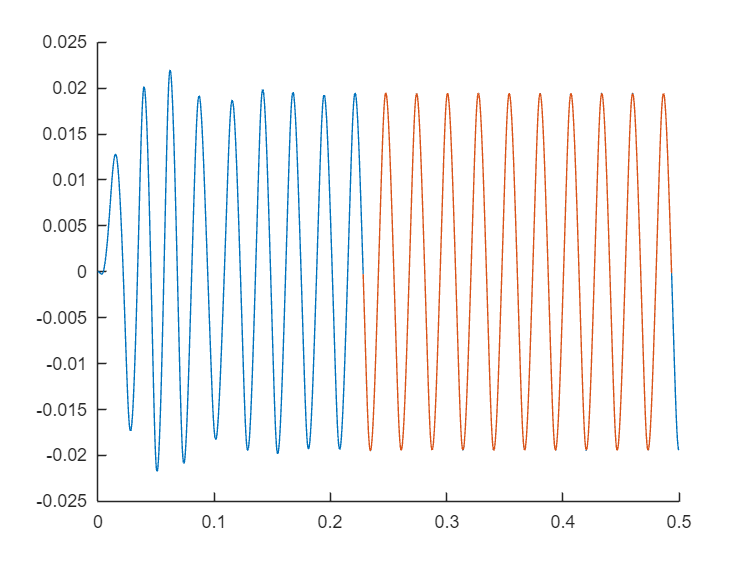

figure;
hold on;
plot(t, tip_disp)
plot(t_lin, x_lin)

## Sweep

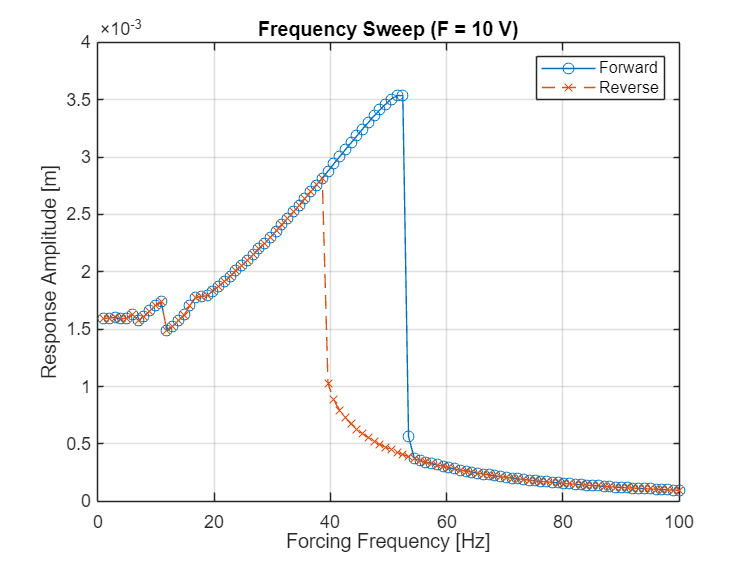

w_vals = linspace(1, 100, 101) * 2*pi;  % Forward sweep (rad/s)
w_vals_rev = fliplr(w_vals);          % Reverse sweep

A_response_fwd = zeros(size(w_vals));
A_freq_fwd = zeros(size(w_vals));

A_response_rev = zeros(size(w_vals));
A_freq_rev = zeros(size(w_vals));

% ---------- Forward sweep ----------
for i = 1:length(w_vals)
    w1 = w_vals(i);
    tspan = [0, 30/(w1/(2*pi))]; % ensures 30 periods

    model.omega = w1;  % Update model omega
    model.u_fun = @(t) model.F * sin(w1 * t);

    [t, x] = ode15s(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
    
    % tip_disp = x(:,1:2) * model.Phiell;
    tip_disp = x(:,1);
    [t_lin, x_lin] = f_get_last_n_periods(t, tip_disp, 10);
    [A_vec, B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    A_response_fwd(i) = sqrt(sum(A_vec.^2 + B_vec.^2));

    A_freq_fwd(i) = w1 / (2*pi);  % Convert to Hz

    x0 = x(end,:)';  % continue from last state
end

% ---------- Reverse sweep ----------
for i = 1:length(w_vals_rev)
    w1 = w_vals_rev(i);
    tspan = [0, 30/(w1/(2*pi))]; % ensures 30 periods

    model.omega = w1;
    model.u_fun = @(t) model.F * sin(w1 * t);

    [t, x] = ode15s(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);

    % tip_disp = x(:,1:2) * model.Phiell;
    tip_disp = x(:,1);
    [t_lin, x_lin] = f_get_last_n_periods(t, tip_disp, 10);
    [A_vec, B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    A_response_rev(i) = sqrt(sum(A_vec.^2 + B_vec.^2));

    A_freq_rev(i) = w1 / (2*pi);

    x0 = x(end,:)';  % continue from last state
end

% ---------- Plot ----------
figure;
plot(A_freq_fwd, A_response_fwd, 'o-', 'DisplayName', 'Forward');
hold on;
plot(A_freq_rev, A_response_rev, 'x--', 'DisplayName', 'Reverse');
xlabel('Forcing Frequency [Hz]');
ylabel('Response Amplitude [m]');
title(['Frequency Sweep (F = ', num2str(model.F), ' V)']);
legend('Location','northeast');
grid on;